clear 
clc
fs = 41.667e3;
sweepDur = 20;
silenceDur = 2;
%tone = sweeptone(sweepDur,silenceDur,fs, 'SweepFrequencyRange', [20 20.8e3])*2;
%toneNoSilence = tone(1:end-round(silenceDur*fs)-1)


f1 = 20;
f2 = 20.8e3;
tone = sweeptone(sweepDur,silenceDur,fs, 'SweepFrequencyRange', [f1 f2])*2;
invTone = flip(tone(1:end-silenceDur*fs))' .* (f2 / f1).^(-(0:(sweepDur*fs-1)) / (sweepDur*fs-1));
tone = [zeros(silenceDur*fs-1,1); tone];
t = 0:1/fs:sweepDur+(silenceDur-1/fs)*2;
tInv = 2:1/fs:(sweepDur+2)-1/fs;


sineTone = sin(2*pi*(0:1/fs:sweepDur)*1000);%.*linspace(0,1,sweepDur*fs+1);
sineTone = [zeros(1,silenceDur*fs-1) sineTone zeros(1,silenceDur*fs-1)];

initialSine = sin(2*pi*(0:1/fs:fs/1000*1/fs)*1000);%*0.5;
tone(round(1*fs):(round(1*fs)+length(initialSine)-1)) = initialSine;
audiowrite("expSweptSineSync2s20s2s.wav",tone,fs)

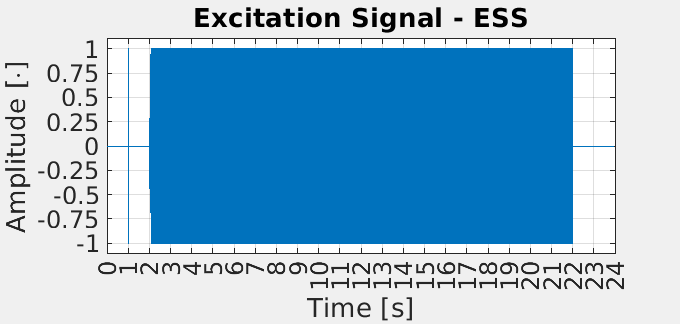


%audiowrite("sine1000Hz2s10s2s.wav",sineTone,fs)

set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 11])
plot(t,tone)
hold on
title('Excitation Signal - ESS', 'FontSize', 22)
xlabel('Time [s]', 'FontSize', 20)
ylabel('Amplitude [\cdot]', 'FontSize', 20)
grid
ylim([-1.1 1.1])
xlim([0 24])
ytickList = linspace(-1,1,9);
yticks(ytickList(1:1:end))
yticklabels(string(ytickList(1:1:end)))
xtickList = linspace(0,24,25);
xticks(xtickList(1:1:end))
xticklabels(string(xtickList(1:1:end)))
ax = gca;
ax.FontSize = 18;
hold off

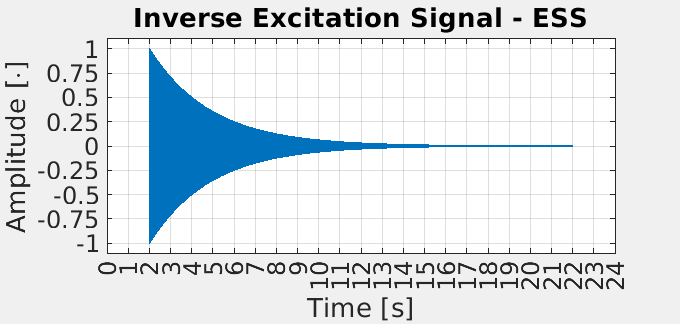

%exportgraphics(gcf,'ESSExcitationIdentifier.pdf')

set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 11])
plot(tInv,invTone)
hold on
title('Inverse Excitation Signal - ESS', 'FontSize', 22)
xlabel('Time [s]', 'FontSize', 20)
ylabel('Amplitude [\cdot]', 'FontSize', 20)
grid
ylim([-1.1 1.1])
xlim([0 24])
ytickList = linspace(-1,1,9);
yticks(ytickList(1:1:end))
yticklabels(string(ytickList(1:1:end)))
xtickList = linspace(0,24,25);
xticks(xtickList(1:1:end))
xticklabels(string(xtickList(1:1:end)))
ax = gca;
ax.FontSize = 18;
hold off

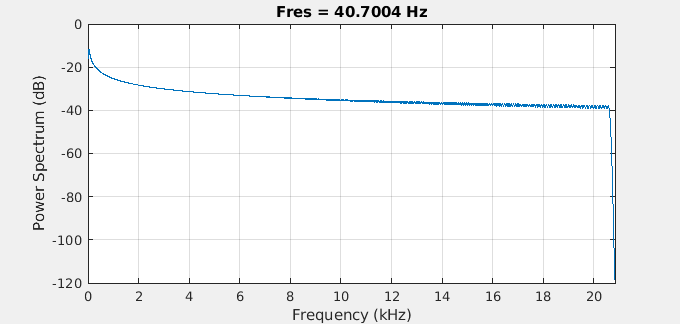

%export

toneNoSilence = tone(2*fs:end-2*fs-1);

%spectrogram(toneNoSilence,fs)
%pwelch(toneNoSilence,fs)
pspectrum(toneNoSilence,fs)

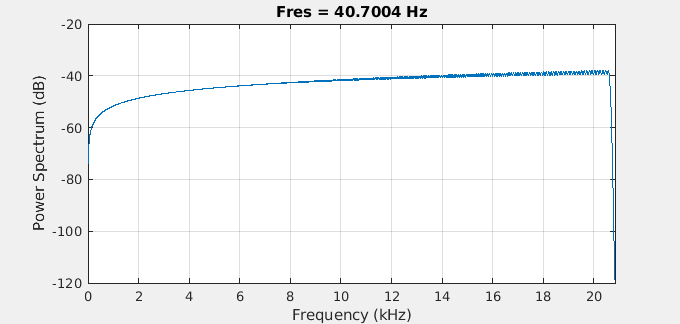

pspectrum(invTone,fs)

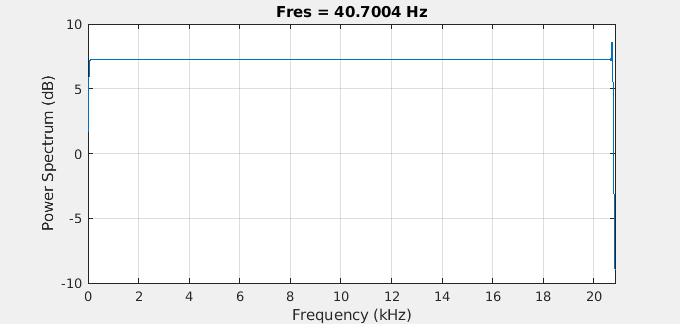

pspectrum(conv(toneNoSilence,invTone),fs)

%pspectrum(impzest(tone,tone),fs)
%[S, F, ~] = stft(tone(2*fs:end-2*fs-1),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
%plot(linspace(2,12,length(S)),mag2db(max(abs(S))))


%t = linspace(0,length(tone)/fs,length(tone))
%plot(t,tone)
%pspectrum(tone,fs)






% cfULA1 = 1700;
% cfULA2 = [cfULA1 4500];
% cfULA3 = cfULA2(2);
% FIRULA1 = fir1(60, 2*cfULA1/fs, 'low');
% FIRULA2 = fir1(60, 2*cfULA2/fs, 'bandpass');
% FIRULA3 = fir1(60, 2*cfULA3/fs, 'high');

%toneFiltered = filter(FIRULA1,1,tone) + filter(FIRULA2,1,tone) %+ filter(FIRULA3,1,tone);
%impulse = impzest(tone, toneFiltered);
%impulse = impulse(1:101);

%impulse = impzest(tone,tone)
%plot(impulse)
%pwelch(impulse,fs)
%pspectrum(impulse,fs) %psectrum STINKER